## Dubins Path Computation

Helper script to compute shortest dubin's path. Define the test input.

startPose = [1, 2, pi/4];
goalPose = [0, -1, 0];

### This is showing the matlab's Dubin functionality (from robotics toolbox) - used as a reference to validate our implementation.

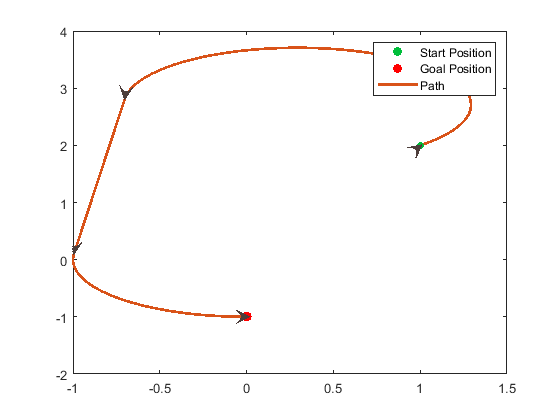

conn = robotics.DubinsConnection;
% conn.MinTurningRadius = 4;
pathCalculator = connect(conn,startPose, goalPose);
pathSeg = pathCalculator{1};
show(pathSeg);

fprintf('path : %s\n', pathSeg.MotionLengths);

path : 3.819216e+00
path : 2.722905e+00
path : 1.678571e+00


fprintf('optimalMode : %s\n', strjoin(pathSeg.MotionTypes));

optimalMode : L S L


fprintf('optimalCost : %s\n', pathSeg.Length);

optimalCost : 8.220692e+00


### This is from our implementation. The values shown here should match the values shown above.

[motion_lengths, motion_types, optimalDistance, path] = computeDublin.computeDubinsPath(startPose, goalPose, 1);

Undefined function or variable 'computeDubinsInternal'.

Error in computeDublin.computeDubinsPath (line 10)
            [motion_lengths, motion_types, optimalCost, path] = computeDubinsInternal([lex, ley, diff(3)], c);

fprintf('path : %s\n', motion_lengths);
fprintf('optimalMode : %s\n', motion_types);
fprintf('optimalCost : %s\n', optimalDistance);

### This is interpolation from existing matlab classes...

  % Create a connection mechanism object
  turningRadius         = 1;
  numInterpolationSteps = 20;
  connectionDistance    = 10;

  connMech = matlabshared.planning.internal.DubinsConnectionMechanism;
  connMech.TurningRadius      = turningRadius;
  connMech.NumSteps           = numInterpolationSteps;
  connMech.ConnectionDistance = connectionDistance;

  % Find the Dubins distance between two poses
  d = connMech.distance(startPose, goalPose)

d = 8.2207


  % Find wayposes between two poses along Dubins curve.
  poses = connMech.interpolate(startPose, goalPose)

poses =    -0.7013    2.8147    4.6046
   -0.9942    0.1076    4.6046
    1.2236    2.3414    1.1964
    1.2922    2.7438    1.6075
    1.1943    3.1400    2.0185
    0.9463    3.4641    2.4295
    0.5894    3.6621    2.8406
    0.1831    3.7011    3.2516
   -0.2049    3.5744    3.6626
   -0.5100    3.3033    4.0737
